## Figure 1B&D: generate the flat and bumpy firing rate

Parameters of the biophysical model (Milstein et. al. 2021)

For the plasticity:

- $\tau_{eligibility}$ = 1664.103 ms

- $\tau_{instractive}$= 737.0065 ms

- $\alpha_{pot}$ = 4.150117E-01   old parameter setup

- $\beta_{pot}$ = 2/(4.541096E-01 +0.1)

- $\alpha_{dep}$ = 2.618154E-02;

- $\beta_{dep}$= 2/(9.977173E-02 +0.045); 

- $k_{potentiation}$ = 0.9;

- $k_{depression}$ = 0.275

    tau_elig = 1.664103 * 1000  ; % timescale for local signal

    tau_inst = 4.370065E-1 * 1000 + 300;  % timescale for global signal

    alpha_pot = 4.150117E-01;

    beta_pot =  2/(4.541096E-01 +0.1);

    alpha_dep = 2.618154E-02;

    beta_dep = 2/(9.977173E-02 +0.045);     

    k_pot = 0.9;

    k_dep = 0.275;

Simulation setup:

- L = 187 cm    length of track

- v = 25 cm/s    velocity

- N = 100.

Parameters of the 1D map (proposed model):

For the plasticity, v = 25:

- Potentiation: $\nu$ (degree) = 3.5 $\mu$ (location) =  0.685, $\sigma$ (scale) = 1.65, $\lambda$ (skewness) = -1.61.

- Depression:  $\nu$ =  5, $\mu$ = 1.75, $\sigma$ = 3.65, $\lambda$ =  -5.35.

Simulation Setup:

- L = 187 cm

- v = 25 cm/s

- N = 400.

For each speed, the shape of plasticity in the biophysical model is different. So, we have to adjust the parameter of wrapped skew-t distribution  to fit the plasticity.

For more detail, please the script ***pot_dep_func.m*** including the parameter setting.

clear; clc
velocity = 25;      L = 187;        init_weight = 0;        n_ca3_bio = 100;    n_ca3_map = 400;
inductions = [1, L/2];
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = ...
    Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3_map);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = ...
    Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3_bio);
save Files/weight_matrix/Fig1/Simulations.mat

## Figure 1G: generate the heapmap of weight change due to the BTSP

To get more precision of figure G, the number of CA3 cell is also set to 400.

n_ca3_bio = 400;
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = ...
    Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3_map);
save Files/weight_matrix/Fig1/Simulations_heatmap.mat

## Figure 1H: generate the synaptic weight after two consecutive inductions

We run the same simulation but change the number of cells for bio model to 100, first induction at position 30 cm at lap 1, and second at 90cm at lap 3.

inductions = [1, 30; 3, 90];
n_ca3_bio = 100;

[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = ...
    Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3_map);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = ...
    Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3_bio);
save Files/weight_matrix/Fig1/Simulations_two_inductions.mat

## Figure 2B: Generate weight matrix before learning and after learning.

Parameters of simulation: 

- N (n_ca3_per_track) = 256,

- n (number of explored environments) = 50

- P (learning constant for potentiation) = D (for depression) = 0.3.

Using previous parameters, we run simulation ( **Sim_CA3RecNetowrk** function) to obtain the updated weight matrix.

The same weight matrix are used to represent the figure 2B, 2D and 2E.

n = 50;                     % number of environment that animal need to explore
M = 1;                      % number of cells that encode the same position in the track
s = 1;                      % sparsity 0 indicate very^very sparse, 1 indicate the whole net
n_ca3_per_track = 2^8;
P = 0.3;
D = 0.3;

plot_figure = false;
seed = 1997;

[phase, Env_track, final_weight, weight_before, weight_mean, weight_var] = ...
    Sim_CA3RecNetowrk(n_ca3_per_track, n, M, s, P, D, plot_figure, seed);
save Files\weight_matrix\Fig2\weight.mat

## Figure 3C: amplitude and mean variance VS number of past environment $\eta$

Parameters of simulation:

- $N$ = 128

- $n = 125$ for $s$ = 1, $n = 200$ for $s = 0.5$, and $n = 1000$ for $s = 0.1$.

- $M = 1, 10, 100$ for $s = 1$, and $s = 0.1, 0. 5$ for $M = 100$ (second block).

- $P = D= 0.3$.

For different parameter set (M, s), we run simulation to obtain steady steate weight matrix then compute the amplitude and mean of variance (first and second blocks). Later, we also compute the analytical results of mean weight curve and variance to make the comparison. 

Simulation weight simulation for  M = 1 and 10 fixing  s = 1;

        1987



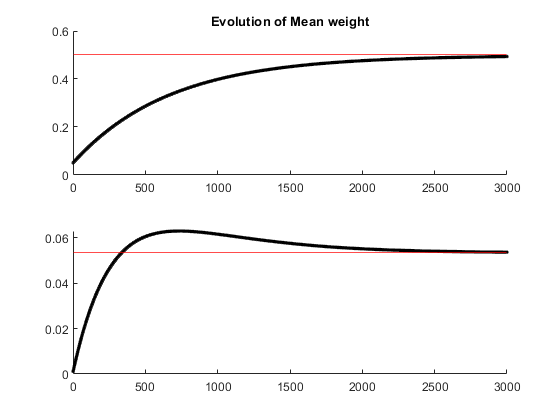

clear; clc;
N_per_track = 128;    % number of cells that encode environment
n = 125;                  % number of environment that animal need to explore
P = 0.3;
D = 0.3;
etas = [linspace(log(1), log(10), 6), linspace(log(10), log(100), 6)];
etas = [0, round(exp(etas))];
etas_sim = unique(etas);
use_gpu = true;
plot_figure = false;
is_stack = true;

s = 1;                    % sparsity 0 indicate very^very sparse, 1 indicate the whole net
M = [100, 10, 1];
%M = 100;

ampl_s1_sim = zeros(length(M), length(etas_sim));
var_s1_sim = zeros(length(M), length(etas_sim));
seed = 1997;
for i = 1:length(M)
    M_i = M(i);
    [phase, Env_track, synaptic_weight] = Sim_CA3RecNetowrk(N_per_track, n, M_i, s, P, D, ...
        plot_figure, seed, use_gpu);
    
    %parfor (j = 1:length(etas_sim))
    for j = 1:length(etas_sim)
        eta_j = etas_sim(j);
        % sort the weight
        [sorted_weight, phase_corrected] = Aligment(synaptic_weight, Env_track, eta_j, ...
            phase, N_per_track, M_i, s);
        % compute the amplitude
        
        Mean_by_column = mean(sorted_weight);
        Var_by_column = var(sorted_weight - Mean_by_column);
        
        Mean_sim = grpstats(Mean_by_column, phase_corrected, "mean");
        Var_sim = grpstats(Var_by_column, phase_corrected, "mean") / (M_i * s);
        
        f_fft = fft(Mean_sim);
        amplitude = 2 * abs(f_fft(2)) / N_per_track;
        
        % save
        ampl_s1_sim(i, j) = gather(amplitude);
        var_s1_sim(i, j) = gather(mean(Var_sim));
        % clear sorted_weight phase_corrected f_fft f_abs amplitude var_sim var_mean
    end
    synpatic_weight = []; phase = []; Env_track = [];
end

aux = ampl_s1_sim(1, :);
ampl_s1_sim(1, :) = ampl_s1_sim(3, :);
ampl_s1_sim(3, :) = aux;

aux = var_s1_sim(1, :);
var_s1_sim(1, :) = var_s1_sim(3, :);
var_s1_sim(3, :) = aux;
% the order should be 1 10 and 100, but with my laptop the m = 100 should

% be run firstly.

save Files\weight_matrix\Fig3\mean_var_s1.mat etas_sim ampl_s1_sim var_s1_sim N_per_track n P D M s

Simulation weight simulation for  s = 0.1 and 0.5 fixing  M = 100;

clear; clc;
N_per_track = 128;    % number of cells that encode environment
n = [1000, 200];                  % number of environment that animal need to explore
P = 0.3;
D = 0.3;
etas = [linspace(log(1), log(10), 6), linspace(log(10), log(100), 6)];
etas = [0, round(exp(etas))];
etas_sim = unique(etas);
use_gpu = true;
plot_figure = true;
is_stack = true;

M = 100;                    % sparsity 0 indicate very^very sparse, 1 indicate the whole net
s = [0.1, 0.5, 1];
%M = 10;

ampl_M100_sim = zeros(length(s), length(etas_sim));
var_M100_sim = zeros(length(s), length(etas_sim));
seed = 1997;

for i = 1:(length(s)-1)
    
    s_i = s(i);
    [phase, Env_track, synaptic_weight] = Sim_CA3RecNetowrk(N_per_track, n(i), M, s_i, P, D, ...
        plot_figure, seed, use_gpu);
    
    for (j = 1:length(etas_sim))
        eta_j = etas_sim(j);
        display(eta_j)
        % sort the weight
        [sorted_weight, phase_corrected] = Aligment(synaptic_weight, Env_track, eta_j, phase, ...
            N_per_track, M, s_i);
        % compute the amplitude
        
        Mean_by_column = mean(sorted_weight);
        Var_by_column = var(sorted_weight - Mean_by_column);
        
        Mean_sim = grpstats(Mean_by_column, phase_corrected, "mean");
        Var_sim = grpstats(Var_by_column, phase_corrected, "mean") / (M*s_i);
        
        f_fft = fft(Mean_sim);
        amplitude = 2 * abs(f_fft(2)) / N_per_track;
        
        ampl_M100_sim(i, j) = gather(amplitude);
        var_M100_sim(i, j) = gather(mean(Var_sim));
        % clear sorted_weight phase_corrected f_fft f_abs amplitude var_sim var_mean
    end
    synpatic_weight = []; phase = []; Env_track = [];
end

% save the amplitude and variance of M = 100 and s = 1 from previous block.
load Files\weight_matrix\Fig3\mean_var_s1.mat

ampl_M100_sim(3, :) = ampl_s1_sim(3, :);
var_M100_sim(3, :) = var_s1_sim(3, :);

save Files\weight_matrix\Fig3\mean_var_M100.mat etas_sim ampl_M100_sim var_M100_sim N_per_track n P D M s

# **Figure 4: Network dynamics shaped by BTSP in the presence of sparse coding are equivalent to a hierarchy of weakly-interacting ring models ** 

## Figure 4A:  Simulations suggest that the network model can be approximatedd by a series of ring models in sparse limit.

For $s= 0.1$, we run firing rate simulations for different initial conditions, i.e. different environment.  

%
clear; clc;
load Files\weight_matrix\Fig4\P=0dot3D=0dot3\W_M=60_s=0dot1_seed_2022.mat  

w0 = -0.25;
w_max = 40;
weights_network = w_max * (final_weight - mean(final_weight, "all")) + w0;
clear final_weight
weights_network = gpuArray(weights_network);

[tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup();

max_time = 1; % a second
max_steps = max_time * 1000 / d_t + 50;

eta_1 = 0;  % run simulation on the environment n-eta
eta_IC = eta_1; % give initial bump for cells that actived in the environment n-eta_IC
[~, FR_tracker_eta0] = FR_simulation(n_ca3_per_track, M, s, Env_track, phase, weights_network, eta_1, eta_IC, I0, d_t, tau, err, ...
            check_dynamic, plot_mean, nan, max_steps);
eta_2 = 1;
eta_IC = eta_2;
[~, FR_tracker_eta1] = FR_simulation(n_ca3_per_track, M, s, Env_track, phase, weights_network, eta_2, eta_IC, I0, d_t, tau, err, ...
            check_dynamic, plot_mean, nan, max_steps);

eta_3 = 10;  % run simulation on the environment n-eta
eta_IC = eta_3; % give initial bump for cells that actived in the environment n-eta_IC
[~, FR_tracker_eta10] = FR_simulation(n_ca3_per_track, M, s, Env_track, phase, weights_network, eta_3, eta_IC, I0, d_t, tau, err, ...
            check_dynamic, plot_mean, nan, max_steps);

save Files\weight_matrix\Fig4\FR_illustration.mat FR_tracker_eta0 FR_tracker_eta1 FR_tracker_eta10 eta_1 eta_2 eta_3 n Env_track phase d_t

## Figure 4C: Amplitude of the bump vs $w_1$ for $w_0$ < 0 

#### Run firing rate simulation for network model using different weight matrices.

Using a quadratic response function, there is a bistable regim as function of w1. For each weight matrix and for each past environment, we run simulation with two different intial conditions:

- small bump with noise, correponds to lower branch of the response functon;

- large bump with noise, corresponds to upper branch.

#### Simulation for the network model.

We first simulate the connectivity matrix using 1D BTSP with following  parameters.

- $N$: number of cell position on the track

- $n$: number of explored environments (each one are different)

- $M$: the network size

- $s$ : the sparsity

- $P$: constant learning for potentiation

- $D$: for depression

Once fixed the parameters, we run simulation using 1D BTSP.

For each weight matrix there are 2 different sources of randomnes: the initial synaptic weight (0 + unif([0, 0.1])) and random permutation of cell ids in each environment,

The total of weight matrix is equal to 5 * N_seeds.

clear; clc;
N = 2 ^ 8;  % N
n = 1500;   P = 0.3;    D = 0.3;
MS = 6;      % we fix this value
s = 0.1;    M = MS/s;

N_seeds = 2; % 
Run_Weight_sim_Network(N, n, P, D, M, s, N_seeds)

Firing rate simulation for the network model

clear; clc;

% P and

P = 0.3; D = 0.3; s = 0.1;

Run_FR_Sim_Network(P, D, s)

Firing rate simulation for the ring model with noise

P = 0.3; D = 0.3; include_noise = true;

Run_FR_Sim_ring(P, D, include_noise)

Compute the amplitude of steady firing rate using 1st Fourier mode

clear; clc;

% P, D, s
P = 0.3; D = 0.3; s = 0.1;

compute_FR_amplitude(P, D, s)

is_network = false;
compute_FR_amplitude(P, D, s, is_network)

Axiliar block: check amplitude of network for seeds

clear; clc;

% P, D, and s
P = 0.3; D = 0.3; s = 0.1;

% search weights matrix file on the directory
file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
    "D=" + strrep(string(D), ".", "dot");
if ~exist(file_dir, 'dir')
   error("Directory is not exit!")
end
list_files = look_files_by_pattern(file_dir, "amp");
list_file = list_files(contains(list_files, strrep(string(s), ".", "dot")));
%list_file = list_file([1]);

figure
hold on
for i = 1:length(list_file)
    file = list_file{i};
    load(fullfile(file_dir, file))
    
    if contains(file, "Ring")
        plot(w1s, mean_bump, "k-")
        plot(w1s, mean_flat, "k-")
    else
        plot(w1s, mean_bump, "r.")
        plot(w1s, mean_flat, "r.")
        %plot(w1s, amplitude_T)
    end
end
hold off

xlabel("W1")
ylabel("Amplitude = 2*f_1")
title("Amplitude of Firing VS W1")

## Figure 4D: compute the bump amplitude across all the lags

In the Figure 4C we have the bifurcation diagram for all the 

        1111



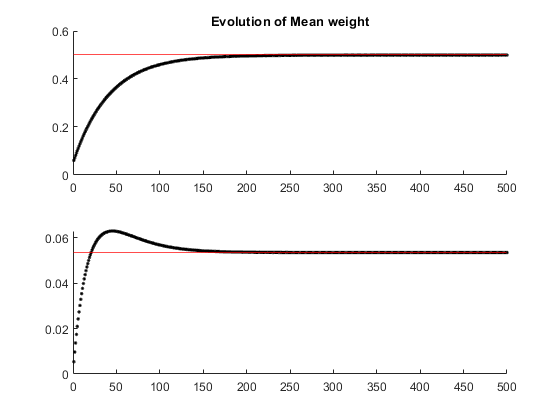

clear; clc;

P = 0.3; D = 0.3; s = 0.1;
desired_w1s = [10, 6, 5, 3.2];

generate_bump_amp_cross_env(P, D, s, desired_w1s);

## Figure 4F: phase diagram of $w_0$ and $w_1$

For each $w_0$ ranged from 1 to -1, we run simulation of ring model start with large $w_1$ and large bumpy initial condition. For the upper branch, we compute the first value of w1 such that the twice of first Fourier mode is larger than a threshold value (named 0.5 according to the diagram of 4D).

The idea is to obtain the last $w1$ such that the large bump solution ends from right to left in the figure 4D.

clear; clc;
load Files\weight_matrix\Fig4\P=0dot3D=0dot3\W_M=60_s=0dot1_seed=1987.mat  n_ca3_per_track phase P D M s n
I0 = 0.2; w_max = 40; 

w0_seq = -1:0.01:0.75;
eta = 150;

phase_ring = unique(phase); M_ring = 1; s_ring = 1; include_noise = true; eta_IC = eta;
Env_track_ring = repmat((1:n_ca3_per_track)', 1, n);

stop_threshold = 0.25;

[tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup();

% generate the saddle-node bifurcation
saddle_node_bif = zeros(length(w0_seq), 1);

% compute unscaled w1
f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;

for i = 1:length(w0_seq)
    w0 = w0_seq(i);
    
    FR_init_ring = zeros(n_ca3_per_track , 1);
    FR_init_ring = FR_init_ring + (1 + cos(phase_ring)) * 1.5;
    
    amplitude = 9999;
    while amplitude >= stop_threshold
        weights_ring = generate_ring_noise_weight(phase_ring, w0, w_max, P, D, M, s, eta, include_noise);
        
        % run simulation for ring model
        [final_Evn, ~, FR, n_step] = FR_simulation(n_ca3_per_track, M_ring, s_ring, Env_track_ring, phase_ring, weights_ring, ...
            eta, eta_IC, I0, d_t, tau, err, check_dynamic, plot_mean, FR_init_ring, max_step, activation_all, tracker);
        
        % FR_init_ring = FR;
        f_fft = fft(final_Evn) / n_ca3_per_track;
        amplitude = 2 * abs(f_fft(2));
        %disp("eta = " + eta + ", amp = " + amplitude)
        
        eta = eta + 1;
    end
    
    desired_eta = eta - 2;
    desired_w1 = w_max * f(P, D, desired_eta, s);
    
    fileID = fopen("Log_bif.txt",'a+');
    fprintf(fileID, 'w0 = %5d, w1 = %5d, Max step = %5d \n', w0, desired_w1, n_step);
    fclose(fileID);
    
    saddle_node_bif(i) = desired_w1;
    eta = eta - 50;
    
    weights_ring = [];FR_init_ring = []; final_Evn = []; FR = [];
end

% generate the Turing bifurcation
turing_bif = zeros(length(w0_seq), 1);
for i = 1:length(w0_seq)
    w0 = w0_seq(i);
    w1_turing = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    turing_bif(i) = w1_turing;
end

save_file = fullfile("Files\weight_matrix\Fig4\", "phase_diagram.mat");
save(save_file, "w0_seq", "turing_bif", "saddle_node_bif", "f", "P", "D", "s", "M", "w_max");

clear; clc;
load Files\weight_matrix\Fig4\P=0dot3D=0dot3\W_M=60_s=0dot1_seed=1987.mat  n_ca3_per_track phase P D M s n
I0 = 0.2; w_max = 40; 

w0_seq = -1:0.01:0.75;
turing_bif = zeros(length(w0_seq), 1);
for i = 1:length(w0_seq)
    w0 = w0_seq(i);
    w1_turing = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    turing_bif(i) = w1_turing;
end
turing_bif_1 = turing_bif;

for i = 1:length(w0_seq)
    w0 = w0_seq(i);
    w1_turing = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    turing_bif(i) = w1_turing;
end

plot(turing_bif_1, w0_seq)
hold on
plot(turing_bif, w0_seq, "k")
hold off

## Fig 5 A, & D panel a: amplitude vs $w_1$ diagram for $s = 0.3, 0.5$  ( $s= 0.2$ sup fig 5A)

$s = 0.3$ is supplementary figure now

Check code description for Fig 4D. This section we run different simulations for different values of s.

#### Weight matrix simulation

clear; clc;
N = 2 ^ 8;  % N
n = [500];   P = 0.3;    D = 0.3;
MS = 6;      % we fix this value

s_seq = [0.2, 0.3, 0.5];

for s = s_seq
    M = MS/s;

    N_seeds = 2; % 
    Run_Weight_sim_Network(N, n, P, D, M, s, N_seeds)
end

#### Firing rate simulation

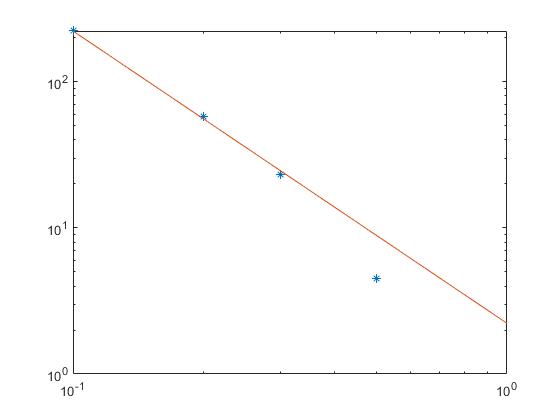

clear; clc;

% P and D

P = 0.3; D = 0.3; s_seq = [0.2, 0.3, 0.5];

s_seq = 0.5;


for s = s_seq
    Run_FR_Sim_Network(P, D, s)
end

#### Run simulation of ring model

Automatically search and run.

P = 0.3; D = 0.3; include_noise = true;

Run_FR_Sim_ring(P, D, include_noise)

#### Compute the amplitude

clear; clc;

% P, D, s
P = 0.3; D = 0.3; s_seq = [0.2, 0.3, 0.5];

for s = s_seq
    compute_FR_amplitude(P, D, s)

    is_network = false; 
    compute_FR_amplitude(P, D, s, is_network)
end

## Fig 5 B, & D panel b: similar to figure 4D but for $s = 0.3, 0.5$ ( $s= 0.2$ sup fig 5B)

clear; clc;
P = 0.3; D = 0.3; 
s = 0.2;
desired_w1s = [10, 6, 5, 2.8];
generate_bump_amp_cross_env(P, D, s, desired_w1s);

s = 0.3;
desired_w1s = [10, 6.16, 5, 2.8];
generate_bump_amp_cross_env(P, D, s, desired_w1s);

s = 0.5;
desired_w1s = [10, 6.3, 5.3, 4.5];
generate_bump_amp_cross_env(P, D, s, desired_w1s);

## Figure 6: comparison of the Network Capacities in different cases.

Cases are:

- The capacity from the $SNR = 1$

- From the Turing bifucation analaysis

- The capacity of saddle node bifurcation of the noised ring model,

- and the network model.

### Generation of the data:

- SNR

clear;clc 
load Files\weight_matrix\Fig6\N=64\W_M=240_s=0dot025_seed_1987.mat  n_ca3_per_track
P = 0.3; D = 0.3; w0 = -0.25; w_max = 40; I0 = 0.2;

sM = 6;
s_seq = unique(exp([linspace(log(0.01), log(0.05), 10), linspace(log(0.05), log(1), 100)]));
M_seq = 6 ./ s_seq;

cap_SNR = zeros(1, length(s_seq));

for i = 1:length(s_seq)
    s = s_seq(i);
    M = M_seq(i);
    eta_crit = -log(8*P*(1-P)*(s*M+1/2)) / 2 / log(1-2*P*s^2);
    cap_SNR(i) = eta_crit;
end

save Files\weight_matrix\Fig6\capacities.mat s_seq M_seq cap_SNR

- Turing of noised ring model

cap_turing = zeros(1, length(s_seq));

for i = 1:length(s_seq)
    s = s_seq(i);
    M = M_seq(i);
    [~, ~, eta_crit] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    cap_turing(i) = eta_crit;
end

save Files\weight_matrix\Fig6\capacities.mat s_seq M_seq cap_SNR cap_turing

- Saddle node from the noised ring model

load Files\weight_matrix\Fig4\P=0dot3D=0dot3\W_M=60_s=0dot1_seed=1987.mat  n_ca3_per_track phase P D M s n

I0 = 0.2; w_max = 40; w0 = -0.25;

eta = 0;

phase_ring = unique(phase); M_ring = 1; s_ring = 1; include_noise = true; eta_IC = eta;
Env_track_ring = repmat((1:n_ca3_per_track)', 1, n);

stop_threshold = 0.25;

[tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup();

s_seq2 = s_seq(s_seq >= 0.05);
% generate the saddle-node bifurcation
saddle_node_bif = zeros(length(s_seq2), 1);

% compute unscaled w1
f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;
s_seq2 = s_seq(s_seq >= 0.05);


for i = length(s_seq2):-1:1
    s = s_seq2(i);
    
    FR_init_ring = zeros(n_ca3_per_track , 1);
    FR_init_ring = FR_init_ring + (1 + cos(phase_ring)) * 1.5;
    
    amplitude = 9999;
    while amplitude >= stop_threshold
        weights_ring = generate_ring_noise_weight(phase_ring, w0, w_max, P, D, M, s, eta, include_noise);
        
        % run simulation for ring model
        [final_Evn, ~, ~, n_step] = FR_simulation(n_ca3_per_track, M_ring, s_ring, Env_track_ring, phase_ring, weights_ring, ...
            eta, eta_IC, I0, d_t, tau, err, check_dynamic, plot_mean, FR_init_ring, max_step, activation_all, tracker);
        
        % FR_init_ring = FR;
        f_fft = fft(final_Evn) / n_ca3_per_track;
        amplitude = 2 * abs(f_fft(2));
        %disp("eta = " + eta + ", amp = " + amplitude)
        
        eta = eta + 1;
    end
    
    desired_eta = eta - 2;
    desired_w1 = w_max * f(P, D, desired_eta, s);
    
    fileID = fopen("Log_bif.txt",'a+');
    fprintf(fileID, 's = %5d, w1 = %5d, eta = %5d, Max step = %5d \n', s, desired_w1, desired_eta, n_step);
    fclose(fileID);
    
    saddle_node_bif(i) = desired_eta;
    eta = max(eta - 5, 0);
    
    weights_ring = [];FR_init_ring = []; final_Evn = []; FR = [];
end

cap_saddle = saddle_node_bif;

save Files\weight_matrix\Fig6\capacities.mat s_seq M_seq cap_SNR cap_turing s_seq2 cap_saddle

- from the network model

P = 0.3; D = 0.3; s_sim = [0.1, 0.2, 0.3, 0.5];

file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");

for i = 1:length(s_sim)
    s = s_sim(i);
    list_files = look_files_by_pattern(file_dir, ["FR", "s=" + strrep(string(s), ".", "dot")]);
    list_files = list_files(not(contains(list_files, "Ring")));
    
    if i == 1
        cap_ind = zeros(length(s_sim), length(list_files));
    end
    
    for j = 1:length(list_files)
        file = list_files(j);
        load(fullfile(file_dir, file), "FR_total", "etas_seq", "Env_track", "phase", "n_ca3_per_track")
        FR_complete = FR_total{1};
        etas = etas_seq(1, :);
        if j == 1
            ite_etas = 0:max(etas);
        end
        
        for k = 1:length(etas)
            FR_comp_k = FR_complete(k, :);
                
            FR_cross_env = zeros(length(ite_etas), size(Env_track, 1)); 
            
            for l = 1:length(ite_etas)
                eta_l = ite_etas(l);
                Env_ind = Env_track(:, end - eta_l);
                FR_cross_env(l, :) = FR_comp_k(Env_ind);
            end
            
            % turn it to cell type
            FR_cross_env_cell = cell(1, 1);
            FR_cross_env_cell{1} = FR_cross_env;
                        % compute the amplitude and turn into a vector
            amp_aux = compute_first_FFT(FR_cross_env_cell, phase, n_ca3_per_track);
            amp_aux = cell2mat(amp_aux);            
            
            stop_ind = sum(amp_aux >= max(amp_aux) * 0.4);
            
            if stop_ind > 1
                cap_ind(i, j) = etas(k-1);
                break
            end
        end
    end
end

mean_cap = mean(cap_ind, 2);

loglog(s_sim, mean_cap, "*")

x_axis = linspace(0.1, 1, 1000);

const = mean_cap(1) * s_sim(1)^2;
y_axis = const ./ x_axis .^2;

hold on
loglog(x_axis, y_axis)
hold off

cap_network = mean_cap;
save Files\weight_matrix\Fig6\capacities.mat s_seq M_seq cap_SNR cap_turing s_seq2 cap_saddle s_sim cap_network

## Suplementary figure 2:

### Panel A:


n_ca3_per_track = 2 ^ 8;    % number of cells that encode environment
n = 50;                     % number of environment that animal need to explore
M = 1;                      % number of cells that encode the same position in the track
s = 1;                      % sparsity 0 indicate very^very sparse, 1 indicate the whole net

P = 0.1;
D = 0.1;

[phase, Env_track, final_weight, weight_before, weight_mean, weight_var] = Sim_CA3RecNetowrk(n_ca3_per_track, n, M, s, P, D, false);
save Files\weight_matrix\SupFig2\PDdot1.mat

### Panel B:

n_ca3_per_track = 2 ^ 8;    % number of cells that encode environment
n = 50;                     % number of environment that animal need to explore
M = 1;                      % number of cells that encode the same position in the track
s = 1;                      % sparsity 0 indicate very^very sparse, 1 indicate the whole net

P = 0.1;
D = 0.3;

[phase, Env_track, final_weight, weight_before, weight_mean, weight_var] = Sim_CA3RecNetowrk(n_ca3_per_track, n, M, s, P, D, false);
save Files\weight_matrix\SupFig2\Pdot1Ddot3.mat

### Panel C:


n_ca3_per_track = 2 ^ 8;    % number of cells that encode environment
n = 50;                     % number of environment that animal need to explore
M = 1;                      % number of cells that encode the same position in the track
s = 1;                      % sparsity 0 indicate very^very sparse, 1 indicate the whole net

P = 0.3;
D = 0.1;

[phase, Env_track, final_weight, weight_before, weight_mean, weight_var] = Sim_CA3RecNetowrk(n_ca3_per_track, n, M, s, P, D, false);
save Files\weight_matrix\SupFig2\Pdot3Ddot1.mat

## Suplementary figure 3: 

### Panel A, B & C: 

clear; clc;
file_name = "Files\weight_matrix\SupFig3\SNR_Capacity.mat";

if not(exist(file_name))
    P = 0.1; D = 0.1;
    [etas, SNR_s1_PDdot1, SNR_M100_PDdot1] = generate_SNR(P, D);
    [asM, Capacity_M_PDdot1, asS, Capacity_s_PDdot1] = generate_capcity(P, D);
    
    P = 0.1; D = 0.3;
    [etas, SNR_s1_Pdot1Ddot3, SNR_M100_Pdot1Ddot3] = generate_SNR(P, D);
    [asM, Capacity_M_Pdot1Ddot3, asS, Capacity_s_Pdot1Ddot3] = generate_capcity(P, D);
    
    P = 0.3; D = 0.1;
    [etas, SNR_s1_Pdot3Ddot1, SNR_M100_Pdot3Ddot1] = generate_SNR(P, D);
    [asM, Capacity_M_Pdot3Ddot1, asS, Capacity_s_Pdot3Ddot1] = generate_capcity(P, D);
    
    save Files\weight_matrix\SupFig3\SNR_Capacity.mat
end

### Panel D & E: 

clear; clc;
s = 1;
storage_capacity = @(M, s, P) -log(8*P.*(1-P)*(s .* M +1/2)) / 2 ./ log(1 - 2*P*s.^2);

M_seq = [1e1, 1e2, 1e3];
p_min = @(x) (1-sqrt((2*x)/(2*x+1)))/2;
precision = 1e6;

capacities = cell(3, 1);
P = cell(3, 1);
for i = 1:length(M_seq)
    M = M_seq(i);
    p_value_min = p_min(M);
    
    P_aux = [linspace(p_value_min, 2*p_value_min, precision * 2), linspace(2*p_value_min, 0.5, precision/2)];
    P_aux = P_aux(P_aux <= 0.5);
    P{i} = P_aux;
    capacities{i} = storage_capacity(M, s, P_aux);
end

M_seq_amx = 10.^(linspace(log10(1e0), log10(1e5), 100));
max_P = zeros(1, length(M_seq));

for i = 1:length(M_seq_amx)
    M = M_seq_amx(i);
    p_value_min = p_min(M);
    
    P_aux = [linspace(p_value_min, 2*p_value_min, precision * 5), linspace(2*p_value_min, 0.5, precision)];
    P_aux = P_aux(P_aux <= 0.5);
    P_aux = unique(P_aux);
    capacities_aux = storage_capacity(M, s, P_aux);
    [cap_max, pos] = max(capacities_aux);
    max_P(i) = P_aux(pos);
end

save Files\weight_matrix\SupFig3\max_P_M.mat

## Suplementary Figure 4: phase diagram of $w_1$ vs $w_0$, $I_0$, $\delta w$.

Similar to Fig 4F, we create three different phase diagrams for the standard ring model to study the effect of the parameters to the firing rate dynamics. 

For the ring model, the dynamic is 

$\tau \frac{d}{dt}r(x,t) = -r(x, t) + \phi\left(<W(x-\cdot), r(\cdot, t)>+I_0\right), \quad <W(x-\cdot), r(\cdot, t)> = \frac{1}{2\pi}\int_{-\pi}^{\pi}dx^\prime W(x-x^\prime)r(x^\prime, t), \quad x \in [-\pi, \pi]$,

where $W(y) = w_0+w_1\cos(y)+\delta w\cdot z(y)$, $z$ is white noise and $\delta w$ modulate the variance of random process.

For phase diagram $w_0$ vs $w_1$, we fix the $I_0= 0.2$ and $\delta w= 0$, then vary the $w_0$ from -1 to 0.75.

For phase diagram $I_0$ vs $w_1$, we fix the $w_0 = -0.25$ and $\delta w = 0$, then vary the $I_0$ form -0.5 to 0.5. 

For phase diagram $\delta w$ vs $w_1$, we fix the $w_0 = -0.25$ and $I_0 = 0.2$, then vary the $\delta w$ from 0 to 1.

clear; clc;
file_dir = "Files\weight_matrix\Fig4\P=0dot3D=0dot3";
save_dir = "Files\weight_matrix\SupFig4";
save_file = "bifurcations.mat";
load(fullfile(file_dir, "W_M=60_s=0dot1_seed=1987.mat"), "n_ca3_per_track", "phase", "P", "D", "M", "s", "n")
w_max = 40; 

phase_ring = unique(phase); 
Env_track_ring = repmat((1:n_ca3_per_track)', 1, n);
phase_matrix = phase_ring - phase_ring';

stop_threshold = 0.25;
[tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup();

which_parameters = 1:3;
n_which = 3;
loop_sets = cell(n_which, 1);
turing_bifs = cell(n_which, 1);
saddle_node_bifs = cell(n_which, 1);    

default_parameters = [-0.25, 0.2, 0];

if exist(fullfile(save_dir, save_file))
    load(fullfile(save_dir, save_file))
    disp("OK\n")
end

for k = 1:length(which_parameters)
    which_parameter = which_parameters(k);
    disp(which_parameter)
    
    switch which_parameter
        case 1
            loop_set = -1:0.01:0.75; % w0
        case 2
            loop_set = [-0.5:0.01:0.5]; % I0
        case 3
            loop_set = [0:0.01:1]; % delta w
        otherwise
	    loop_set = [];
            error("1 for w_0, 2 for I_0, 3 for \delta w.")
    end
    
    
    Parameter_set = default_parameters; % w0, I0, delta w
    w1 = 12; % starting point of w1
    
    % generate the saddle-node bifurcation: results
    saddle_node_bif = zeros(length(loop_set), 1);
    %
    %
    for i = 10:length(loop_set)
        Parameter_set(which_parameter) = loop_set(i); 
        
        FR_init_ring = zeros(n_ca3_per_track , 1);
        FR_init_ring = FR_init_ring + (1 + cos(phase_ring)) * 1.5;
        
        
        amplitude = 9999;
        n_step = 0;
        while amplitude >= stop_threshold && w1 >= 0
            
            if i == 1 && mod(w1, 2) == 0
                disp(w1)
            end
            rng(20230330)
            weights_ring = Parameter_set(1) + w1 * cos(phase_matrix) + Parameter_set(3) * normrnd(0, 1, size(phase_matrix)); 
            
            % run simulation for ring model
            [final_Evn, ~, ~, n_step] = FR_simulation(n_ca3_per_track, 1, 1, Env_track_ring, phase_ring, weights_ring, ...
                0, 0, Parameter_set(2), d_t, tau, err, check_dynamic, plot_mean, FR_init_ring, max_step, activation_all, tracker);
            
            f_fft = fft(final_Evn) / n_ca3_per_track;
            amplitude = 2 * abs(f_fft(2));
            
            w1 = w1 - 0.01;
        end
        
        desired_w1 = w1 + 0.02;
        
        fileID = fopen("Log_bif_sup5.txt",'a+');
        fprintf(fileID, 'parameter_id = %5d, value = %5d, w1 = %5d, Max step = %5d \n', which_parameter, loop_set(i), desired_w1, n_step);
        fclose(fileID);
        
        saddle_node_bif(i) = desired_w1;
        w1 = w1 + 0.5;
        
        weights_ring = [];FR_init_ring = []; final_Evn = []; FR = [];
    end
    %
        % generate the Turing bifurcation
    turing_bif = zeros(length(loop_set), 1);
    for i = 1:length(loop_set)
        Parameter_set(which_parameter) = loop_set(i); 
        
        r0 = (1 - 2 * Parameter_set(1) * Parameter_set(2) - sqrt(1 - 4 * Parameter_set(1) * Parameter_set(2))) ./ (2 * Parameter_set(1) .^2);
        if Parameter_set(1) == 0
            r0 = 0;
        end
        w1_crit_ring = 1 ./(Parameter_set(1) * r0 + Parameter_set(2)) -sqrt(2*pi/n_ca3_per_track) * Parameter_set(3);
        turing_bif(i) = w1_crit_ring;
    end
    
    
    loop_sets{k} = loop_set;
    turing_bifs{k} = turing_bif;
    saddle_node_bifs{k} = saddle_node_bif; 
    
    save_file_aux = fullfile(file_dir, "file_aux_" + string(k) + ".mat");
    save(save_file_aux, "Parameter_set", "default_parameters", "loop_sets", "turing_bifs", "saddle_node_bifs", "P", "D", "s", "M", "w_max");
end


save_file = fullfile(file_dir, save_file);
save(save_file, "Parameter_set", "default_parameters", "loop_sets", "turing_bifs", "saddle_node_bifs", "P", "D", "s", "M", "w_max");

## Suplementary figure 5: Generate the bump profile for different regim

Large bump amplitude

clear; clc;

P = 0.3; D = 0.3; s = 0.1;
seed = 2022;
desired_w1 = 3;

save_file = "Files\weight_matrix\SupFig5\upper_FR.mat";
upper_branch = true;
Run_single_FR_sim(P, D, s, seed, desired_w1, save_file, upper_branch);

desired_w1 = 5.1;
save_file = "Files\weight_matrix\SupFig5\lower_FR.mat";
upper_branch = false;
Run_single_FR_sim(P, D, s, seed, desired_w1, save_file, upper_branch);

## Auxiliar function

function weight_ring = generate_ring_noise_weight(phase, w0, w_max, P, D, M, s, eta, get_noise, is_stack)
    phase = unique(phase);
    
    phase_matrix = phase - phase';
    %is_stack = true; 
    if nargin < 10
        is_stack = true;
    end
    [weight_ring, V] = Compute_mean_variance(P, D, eta, is_stack, M, s, phase_matrix, w0, w_max);

    if get_noise 
        rng(20221213)
        weight_ring = normrnd(weight_ring, 1*sqrt(V));
    end
end

function Run_Weight_sim_Network(n_ca3_per_track, n, P, D, M, s, N_seeds)

    seed_base = [1987, 1991, 1997, 2018, 2022];
    seed_seq = [];
    for i = 1:N_seeds
        seed_seq = [seed_seq, seed_base * i];
    end
    % directory
    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");
    if ~exist(file_dir, 'dir')
       mkdir(file_dir)
    end
    
    save_file_pattern = "\W_M=" + M + "_s=" + strrep(string(s), ".", "dot") + "_seed=";
    
    plot_figure = true;
    use_gpu = true;
    
    for i = 1:length(seed_seq)
        seed = seed_seq(i);
        save_file_name = save_file_pattern + seed + ".mat";
        save_file_name = fullfile(file_dir, save_file_name);
        
        if exist(save_file_name)
            continue
        end
        disp(seed)
        
        [phase, Env_track, final_weight] = Sim_CA3RecNetowrk(n_ca3_per_track, n, M, s, P, D, ...
            plot_figure, seed, use_gpu);
        final_weight = gather(final_weight);
        
        save(save_file_name, "n_ca3_per_track", "n", "P", "D", "M", "s", "phase", "Env_track", "final_weight")
        
        phase = []; Env_track = []; final_weight = [];
    end
end


function Run_FR_Sim_Network(P, D, s, I0, w0, w_max)

    if nargin <4
        % default parameters to produce the figure in the paper
        I0 = 0.2;   w0 = -0.25;     w_max = 40 / (P/(P+D)/0.5) ;
    end
    
    % search weights matrix file on the directory
    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");
    if ~exist(file_dir, 'dir')
       error("Directory is not exit!")
    end
    list_files = look_files_by_pattern(file_dir, ["W_M", "s=" + strrep(string(s), ".", "dot")]);
    
    % run FR simulation for each weight matrix
    for file = list_files
        disp("Loading file: " + file)
        
        save_file = strrep(string(file), "W_", "FR_");
        save_file = strrep(save_file, "_seed", "_w0=" + strrep(string(w0), ".", "dot") ...
            + "_I0=" + strrep(string(I0), ".", "dot") + "_seed");
        
        load_file = fullfile(file_dir, file);
        save_file = fullfile(file_dir, save_file);
        
        if exist(save_file)
            continue
        end
        g = gpuDevice(1); 
        FR_sim_Network(load_file, I0, w0, w_max, save_file)
        reset(g);
    end
end
function Run_FR_Sim_ring(P, D, include_noise, I0, w0, w_max)

    if nargin < 4
        % default parameters to produce the figure in the paper
        I0 = 0.2;   w0 = -0.25;     w_max = 40 / (P/(P+D)/0.5) ;
    end
    
    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");
    
    if ~exist(file_dir, 'dir')
       error("Directory is not exit!")
    end
    list_files_aux = look_files_by_pattern(file_dir, "FR_M");
    aux = cellfun(@(x) cell2mat(extractBetween(x, "FR_", "_seed")), list_files_aux,'UniformOutput',false);
    list_files = unique(aux);
    
    for file = list_files 
        obj_list_files = look_files_by_pattern(file_dir, ["FR_M", string(file)]);
        load_file = obj_list_files{1};
        save_file = extractBefore(load_file, "_seed") + "_Ring.mat";
        
        load_file = fullfile(file_dir, load_file);
        save_file = fullfile(file_dir, save_file);
        
        if exist(save_file)
            continue
        end
        
        FR_sim_Ring(load_file, I0, w0, w_max, save_file, include_noise) 
    end
end


function compute_FR_amplitude(P, D, s, is_network)
    if nargin < 4
        is_network = true;
    end
    
    flat_threshold = 0.1;
    
    % search weights matrix file on the directory
    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");
    if ~exist(file_dir, 'dir')
       error("Directory is not exit!")
    end
    list_files = look_files_by_pattern(file_dir, ["FR_M",  "s=" + strrep(string(s), ".", "dot")]);
    if is_network
        list_files = list_files(not(contains(list_files, "Ring")));
        save_file = "amp_conf_s=" + strrep(string(s), ".", "dot") + ".mat";
    else
        list_files = list_files((contains(list_files, "Ring.mat")));
        save_file = "amp_conf_s=" + strrep(string(s), ".", "dot") + "_Ring.mat";
    end
    
    amplitude_T = cell(2 * length(list_files), 1);
    k = 0;
    for file = list_files
        k = k + 1;
        load(fullfile(file_dir, file))
       
        amp_res = compute_first_FFT(FR_results, phase, n_ca3_per_track);
        
        amplitude_T{k} = amp_res{1};     % eta = 0 to eta = 40
        amplitude_T{k + length(list_files)} = flip(amp_res{2}, 2);    % eta = 40 to eta = 0
    end
    
    % 1:length(list_files) are amplitude for foward simulation, 0 to end. the rest are backward
    amplitude_T = cell2mat(amplitude_T); 
    
    w1s = w1s(1, :);
    
    
    flat_cond = amplitude_T < flat_threshold;
    
    flat_amp = amplitude_T;
    flat_amp(not(flat_cond)) = nan;
    bump_amp = amplitude_T;
    bump_amp(flat_cond) = nan;
    
    mean_flat = mean(flat_amp,'omitnan');
    mean_bump = mean(bump_amp,'omitnan');
    
    var_flat = var(flat_amp,'omitnan');
    var_bump = var(bump_amp,'omitnan');
    
    save(fullfile(file_dir, save_file), "w1s",  "mean_flat", "mean_bump", "var_flat", "var_bump", "amplitude_T", ...
        "P", "D", "M", "s", "w0", "w_max", "I0", "n_ca3_per_track", "etas_seq")
end

function amp_res = compute_first_FFT(FR_results, phase, n_ca3_per_track)
    mean_FR = cellfun(@(x) grpstats(x', phase, {'mean'}), FR_results,'UniformOutput',false);
    amp_res = cell(length(mean_FR), 1);
    for i = 1:length(mean_FR)
        FR = mean_FR{i};
        f_fft = fft(FR', [], 2) / n_ca3_per_track;
        amp_i = 2 * abs(f_fft(:, 2));
        amp_res{i} = amp_i';
    end
end



function list_files = look_files_by_pattern(dir_name, patterns)    
    all_files = dir(dir_name);
    list_files = {all_files.name};
    for pattern = patterns
        list_files = list_files(contains(list_files, pattern));  
    end
end

function [tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup()
    % setup
    tau = 20;
    d_t = 0.5;
    err = 1e-12;
    
    check_dynamic = false;
    plot_mean = true;
    activation_all = false;
    tracker = false;
    max_step = nan;
end

function FR_complete = Run_single_FR_sim(P, D, s, seed, desired_w1s, save_file, upper_branch)

    if nargin < 6
        save_file = "Files\weight_matrix\Fig5\FR_display_s=" + strrep(string(s), ".", "dot") + ".mat";
        upper_branch = true;
    elseif nargin < 7
        upper_branch = true;
    end
   
    % firing rate setup
    [tau, d_t, err, check_dynamic, plot_mean, activation_all, tracker, max_step] = FR_sim_setup();
    % load the weight matrix and other information
    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
            "D=" + strrep(string(D), ".", "dot");
    file_weight = look_files_by_pattern(file_dir, ["W_M", string(seed), "s=" + strrep(string(s), ".", "dot")]);
    load(fullfile(file_dir, file_weight))
    % load the firing rate file to extract information
    file_FR = look_files_by_pattern(file_dir, ["FR", string(seed), "s=" + strrep(string(s), ".", "dot")]);
    load(fullfile(file_dir, file_FR), "etas_seq", "I0", "w0", "w_max", "w1s")
    
    FR_results_compact = zeros(length(desired_w1s), n_ca3_per_track * M);
    eta_compact = zeros(1, length(desired_w1s));
    w1_compact = zeros(1, length(desired_w1s));
    pos_compact = zeros(1, length(desired_w1s));
    
    % setup the weight
    weights_network = gpuArray(w_max * (final_weight - P/(P+D)) + w0);
    clear final_weight
    
    % since we want to check the bump,so the r_base is always 1.5;
    if upper_branch
        r_base = 1.5;
    else
        r_base = I0^2;
    end
    
    for i = 1:length(desired_w1s)
        obj_w1 = desired_w1s(i);
        % find which eta is desired
        [~, pos] = min(abs(w1s(1, :) - obj_w1));
        eta = etas_seq(1, pos);
        w1 = w1s(1, pos);
        % environment and initial condition
        ind_evn = Env_track(:, end - eta);
        FR_init = FR_results_compact(i, :);
        FR_init = FR_init';
        FR_init(ind_evn) = FR_init(ind_evn) + (1 + cos(phase)) * r_base; 
        
        eta_IC = eta;
        [~, ~, FR_res] = FR_simulation(n_ca3_per_track, M, s, Env_track, phase, weights_network, ...
                eta, eta_IC, I0, d_t, tau, err, check_dynamic, plot_mean, FR_init, max_step, activation_all, tracker);
        
        FR_results_compact(i, :) = FR_res;
        eta_compact(i) = eta;
        w1_compact(i) = w1;
        pos_compact(i) = pos;
    end
    
    weights_network = [];
    
    save(save_file, "FR_results_compact",  "eta_compact", "w1_compact", "Env_track", "phase", "seed", "pos_compact", "n_ca3_per_track", "etas_seq")
end


function [etas, SNR_s1, SNR_M100] = generate_SNR(P, D)
    is_stack = true;
    
    etas = linspace(log(1), log(10), 200);
    etas = exp(etas);
    etas = [0, etas/10, etas, etas*10, etas*100];
    etas = unique(etas);
    
    s = 1;
    M = [1, 1e1, 1e2];
    SNR_s1 = zeros(length(M), length(etas));
    for i = 1:length(M)
        M_i = M(i);
        for j = 1:length(etas)
            eta = etas(j);
            [~, V, ~, amp] = Compute_mean_variance(P, D, eta, is_stack, M_i, s);
            SNR_s1(i, j) = amp./sqrt(mean(V));
        end
    end   
    
    M = 1e2;
    s = [0.1, 0.5, 1];
    SNR_M100 = zeros(length(M), length(etas));
    for i = 1:length(s)
        s_i = s(i);
        for j = 1:length(etas)
            eta = etas(j);
            [~, V, ~, amp] = Compute_mean_variance(P, D, eta, is_stack, M, s_i);
            SNR_M100(i, j) = amp./sqrt(mean(V));
        end
    end
end

function [asM, Capacity_M, asS, Capacity_s] = generate_capcity(P, D)
    is_stack = true;
    
    etas_M = 0:0.01:500;

    asM  = linspace(log(1), log(10), 20);
    asM = exp(asM);
    asM = [asM, asM *1e1, asM *1e2, asM *1e3]; 
    
    s = [0.25, 1];
    
    Capacity_M = zeros(length(s), length(asM));

    for k = 1:length(s)
        s_k = s(k);
        for i= 1:length(asM)
            M_i = asM(i);
            SNR_data = zeros(1, length(etas_M));
            parfor j = 1:length(etas_M)
                eta = etas_M(j);
                [~, V, ~, amp] = Compute_mean_variance(P, D, eta, is_stack, M_i, s_k);
                SNR_data(j) = amp / sqrt(mean(V));
            end
            aux = find(SNR_data < 1, 1);
            if isempty(aux)
                Capacity_M(k, i) = etas_M(end);
            elseif aux == 1
                Capacity_M(k, i) = -1;
            else
                Capacity_M(k, i) = etas_M(aux - 1);
            end
        end
    end
    
    etas_s = 0:0.1:1e5;
    M = [1e2, 1e4];
    asS = linspace(log(0.1), log(1), 20);
    asS = exp(asS);
    asS = [asS/10, asS];
    asS = unique(asS);
    
    Capacity_s = zeros(length(M), length(asS));
    is_stack = true;
    compute_amp_var = true;
    for k = 1:length(M)
        M_k = M(k);
        for i= 1:length(asS)
            s_i = asS(i);
            SNR_data = zeros(1, length(etas_s));
            parfor j = 1:length(etas_s)
                eta = etas_s(j);
                [~, V, ~, amp] = Compute_mean_variance(P, D, eta, is_stack, M_i, s_k);
                SNR_data(j) = amp / sqrt(mean(V));
            end
            aux = find(SNR_data < 1, 1);
            if isempty(aux)
                Capacity_s(k, i) = etas_s(end);
            elseif aux == 1
                Capacity_s(k, i) = -1;
            else
                Capacity_s(k, i) = etas_s(aux - 1);
            end
        end
    end
end


function generate_bump_amp_cross_env(P, D, s, desired_w1s)
    save_file = "Amp_cross_s=" + strrep(string(s), ".", "dot") + ".mat";

    file_dir = "Files\weight_matrix\Fig4\P=" + strrep(string(P), ".", "dot") + ...
        "D=" + strrep(string(D), ".", "dot");
    list_files = look_files_by_pattern(file_dir, ["FR", "s=" + strrep(string(s), ".", "dot")]);
    list_files = list_files(not(contains(list_files, "Ring")));
    
    n_w1s = length(desired_w1s);
    mean_bump_amp = cell(n_w1s, 1);
    var_bump_amp = cell(n_w1s, 1);
    which_eta = zeros(1, n_w1s);
    which_w1 = zeros(1, n_w1s);
    
    for i = 1:n_w1s
        % find the nearest value of w1 and eta to w1_obj
        w1_obj = desired_w1s(i);
        % temporaly file
        bump_amp_aux = cell(length(list_files), 1);
        
        % iterate over files
        for j = 1:length(list_files)
            file = list_files(j);
            load(fullfile(file_dir, file))
            
            % create the eta axis
            if i == 1 & j == 1
                eta_max = max(etas_seq(:));
                etas = 0:eta_max;
            end
            
            % find which w1 and eta, and the values remain over iteration i
            if j == 1
                dif_w1 = abs(w1s(1, :) - w1_obj);
                [~, pos_ind] = min(dif_w1);
                which_eta(i) = etas_seq(1, pos_ind);
                which_w1(i) = w1s(1, pos_ind);
            end
            
            % get the complete firing at that environment
            FR_complete = FR_total{1};
            FR_complete = FR_complete(pos_ind, :);
            
            % projection of FR_complete to each of past explored environments
            FR_cross_env = zeros(length(etas), size(Env_track, 1)); 
            
            % iterate over lag
            for k = 1:length(etas)
                eta = etas(k);
                Env_ind = Env_track(:, end - eta);
                FR_cross_env(k, :) = FR_complete(Env_ind);
            end
            % turn it to cell type
            FR_cross_env_cell = cell(1, 1);
            FR_cross_env_cell{1} = FR_cross_env;
            
            % compute the amplitude and turn into a vector
            amp_aux = compute_first_FFT(FR_cross_env_cell, phase, n_ca3_per_track);
            amp_aux = cell2mat(amp_aux);
            
            % save seperately
            bump_amp_aux{j} = amp_aux; 
        end
        
        % turn the cell type to matrix
        bump_amp_aux = cell2mat(bump_amp_aux);
        
        mean_bump_amp{i} = mean(bump_amp_aux);
        var_bump_amp{i} = var(bump_amp_aux);
    end
    
    save(fullfile(file_dir, save_file), "etas", "which_w1", "which_eta", "mean_bump_amp", "var_bump_amp", "desired_w1s");
end

function [w1_crit, w1_crit_ring, eta_crit] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track)
    r0 = (1 - 2*w0*I0 - sqrt(1 - 4*w0*I0)) ./ (2*w0.^2);
    if w0 == 0
        r0 = 0;
    end
    w1_crit_ring = 1 ./(w0*r0+I0);
    
    is_stack = true;
    eta = 0;
    w1_aux = 999;
    while w1_aux > w1_crit_ring
        [~, ~, ~, amp, A, ~, C] = Compute_mean_variance(P, D, eta, is_stack, M, s, nan, w0, w_max);
        w1_aux = amp + sqrt(A + C/2) * sqrt(2*pi/(n_ca3_per_track));
        
        eta = eta + 0.1;
    end

    f = @(P, D, eta, s) 2*P*D./(P+D)*(1-s^2*(P+D)).^eta;
    w1_crit = w_max * f(P, D, eta, s);
    eta_crit = eta;
end